# Gabriel Cardoso 18.00477-6

clear all;
clc;
close all;


## Definindo o sistema dinamico

N = 1

N = 1

D = [1 1]

D =      1     1


Gp = tf(N,D)


Gp =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



## Visualização

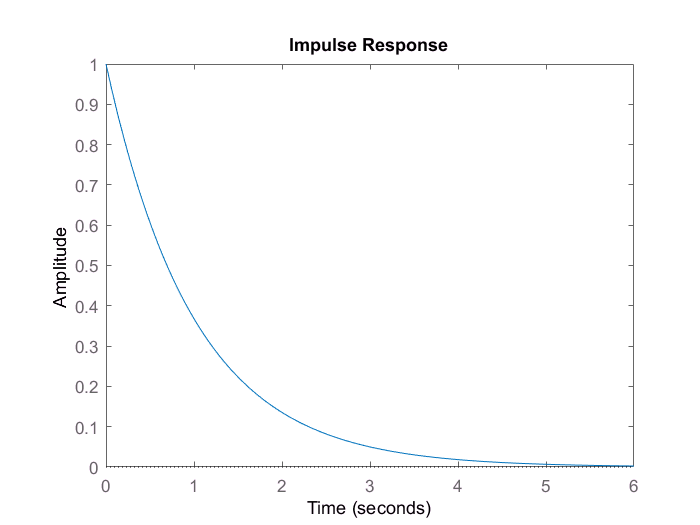

figure()
impulse(Gp)

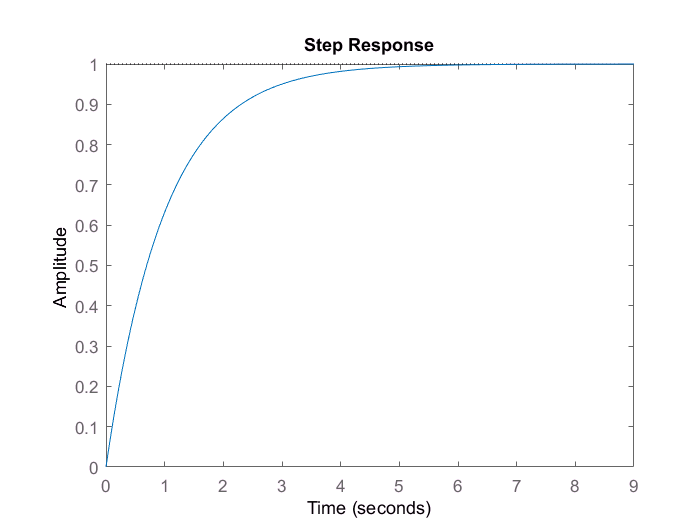

figure()
step(Gp)

## Sistema em Z

T = 0.1;
Nd = 1 -exp(-T);
Dd = [1 exp(-T)];

Gpz = tf(Nd,Dd,T)


Gpz =
 
   0.09516
  ----------
  z + 0.9048
 
Sample time: 0.1 seconds
Discrete-time transfer function.



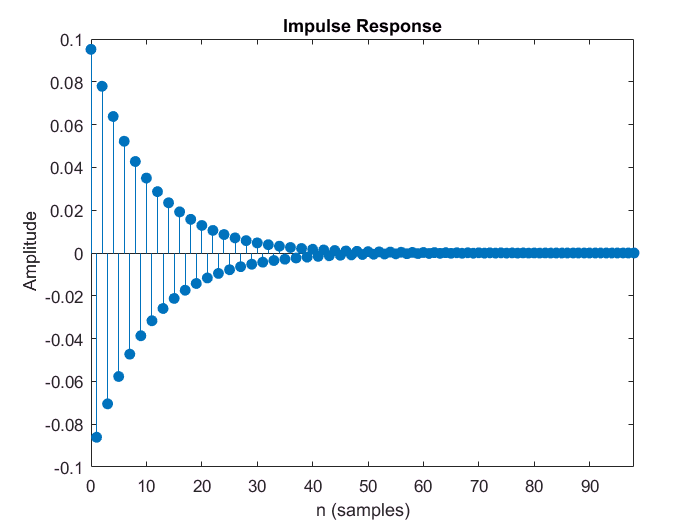


impz(Nd, Dd)


figure()

step(Gp)

## Equações de diferenças


$$\frac{Y(z)}{U(z)} = \frac{a}{z-b} = \frac{az^{-1}}{1 - bz^{-1}}$$



$$y(n) = au(n-1) + by(n -1 )$$


%% Trabalho

%Gfiltro(s) = wc/(s + wc)


aux = jsondecode(fileread('accelerometer_data (1).json'))

Undefined function 'jsondecode' for input arguments of type 'char'.



plot(vertcat(aux.timestamp), vertcat(aux.z))

tempo = vertcat(aux.timestamp)

T = mean(diff(tempo))

Ac_x = vertcat(aux.x);
Ac_x_W = fft(Ac_x);
fs = 1/T;
M = lenght(Ac_x);
freq = linspace(-fs/2,fs/2,M)



stem(freq,abs(fftshift(Ac_x_W)))
xlabel('Frequencia em Hz')

%% Determinando a potencia versus a banda

Pot_total = sum(abs(Ac_x_W).^2)
Espectro_Unilateral = Ac_x_W(M/2+1:end)

figure()

stem(freq(M/2+1:end),abs((Espectro_Unilateral)))

xlabel('Frequencia em Hz')

figure()

stem(freq(M/2+1:end),cumsum(abs((Espectro_Unilateral)).^2))

xlabel('Frequencia em Hz')

%portanto 

wx = 2*pi*2

N = wc

D = [1 N]

gfiltro = tf(N,D)


